# A simple Fingerprinting demo

clear;

% Find base repository path (where this file is contained)
basePath = fileparts(which('demo_reembedding.mlx'));
% Add to MATLAB path
idcs   = strfind(basePath,filesep);
addpath(genpath(fullfile(basePath(1:idcs(end)-1))));

% load LEAP output and plot body parts predictions for fragment of the movie
jj=double(h5read("demo_MMM_LEAPpred.h5", '/positions_pred'));
juse = [1 2 5 6 7 8 12 13 14 15 16];
jplot = [1 8 7 12 13 16 17 18];
idxs = 40001:49600;
% load 8 behavior classes
load("demo_MMM_sC1CON.mat")

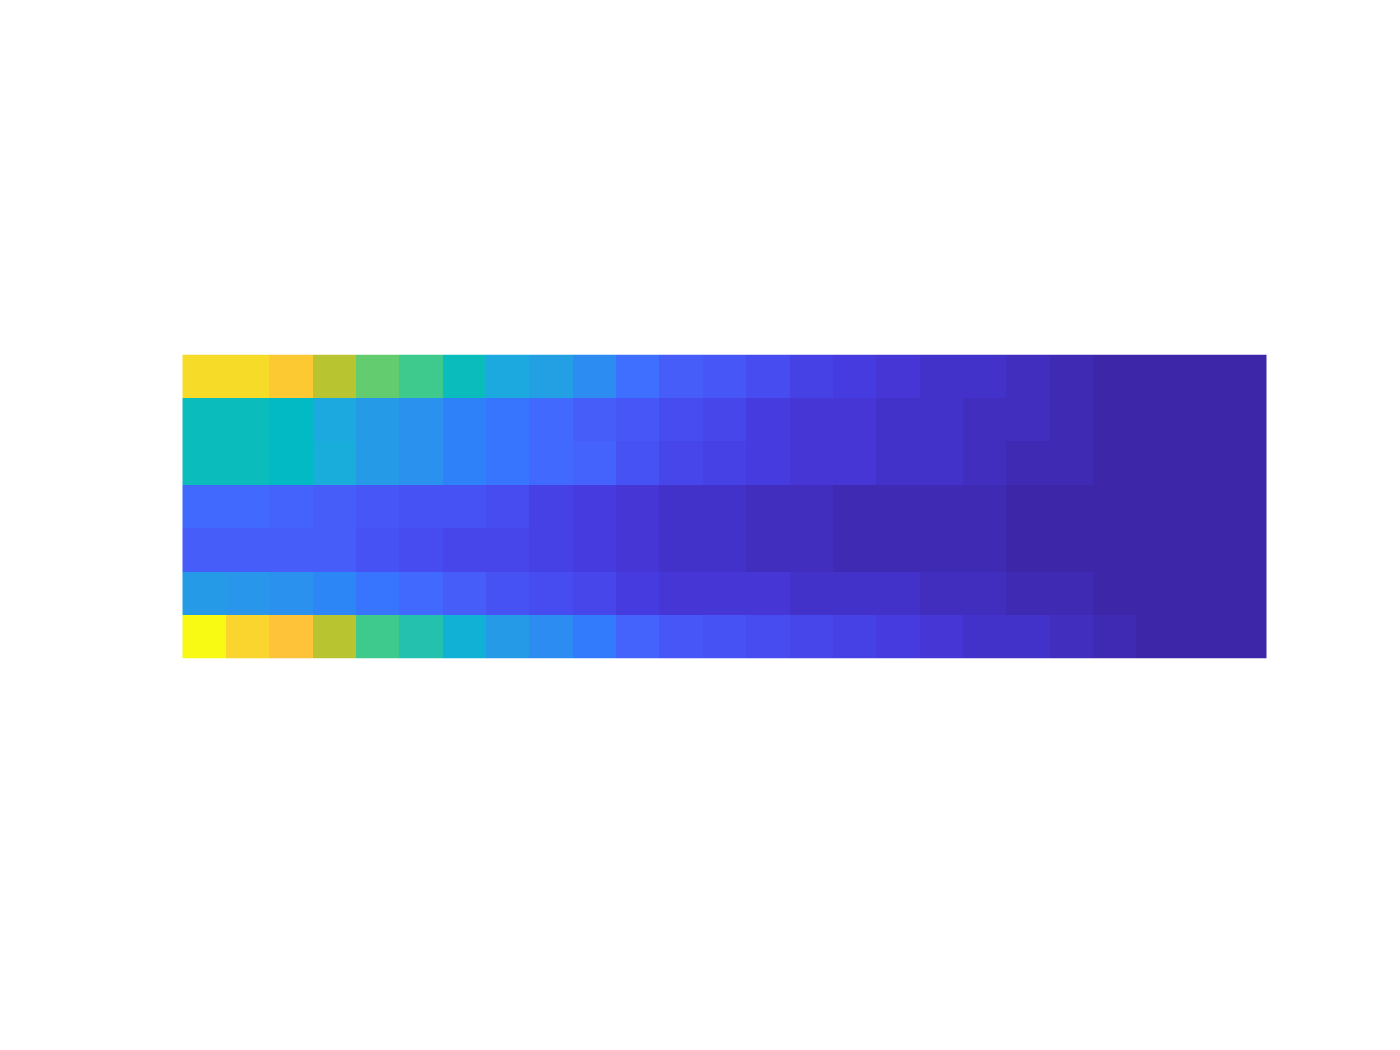

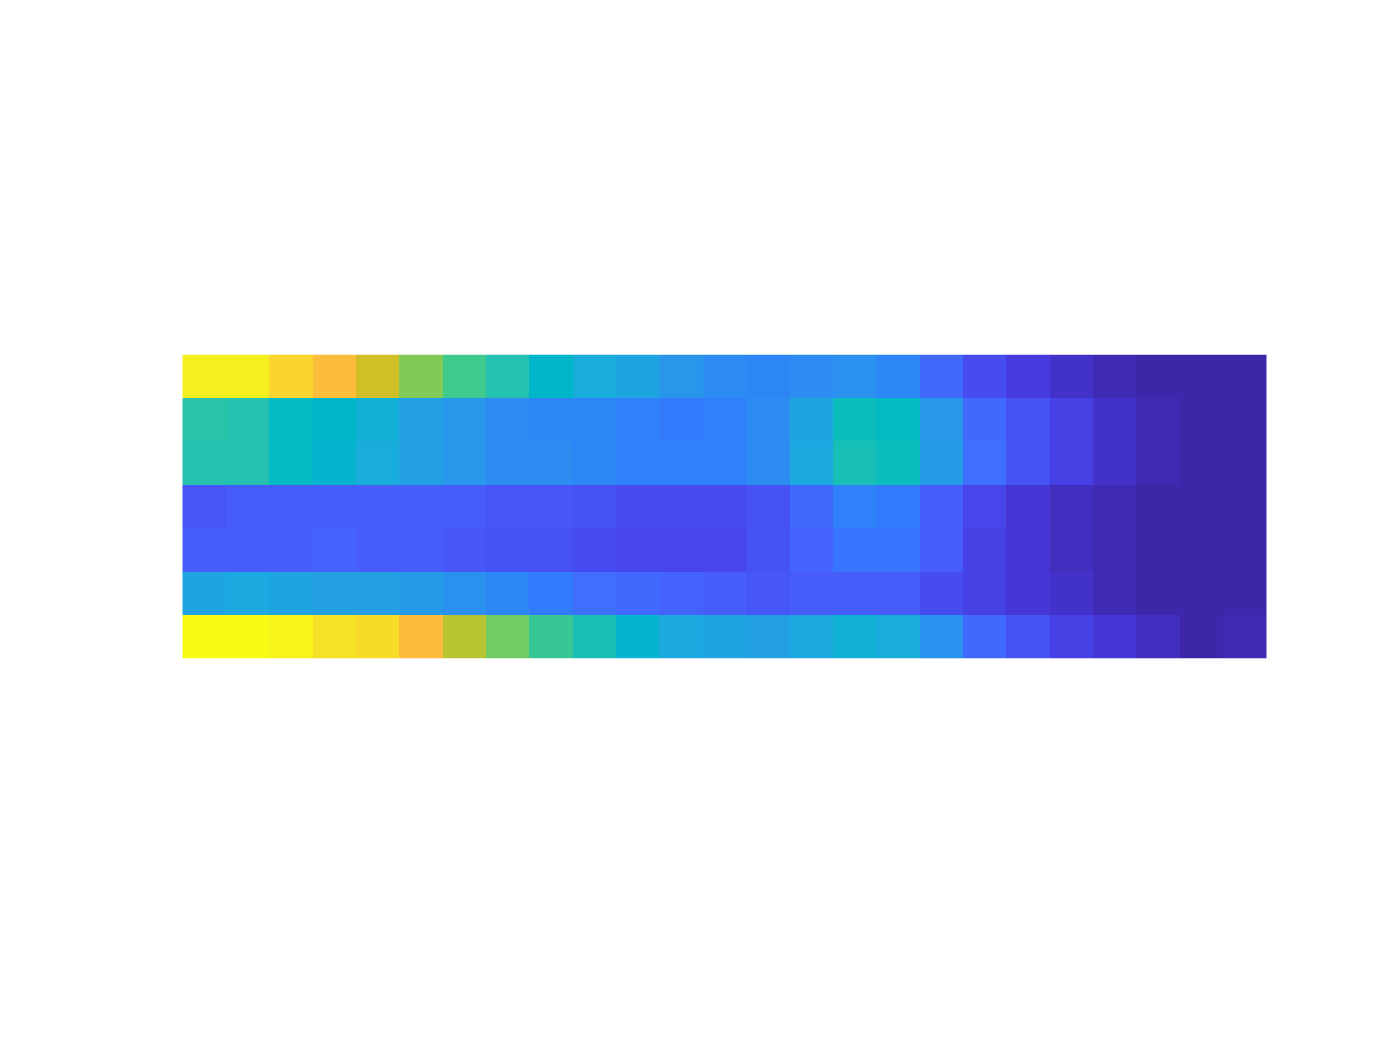

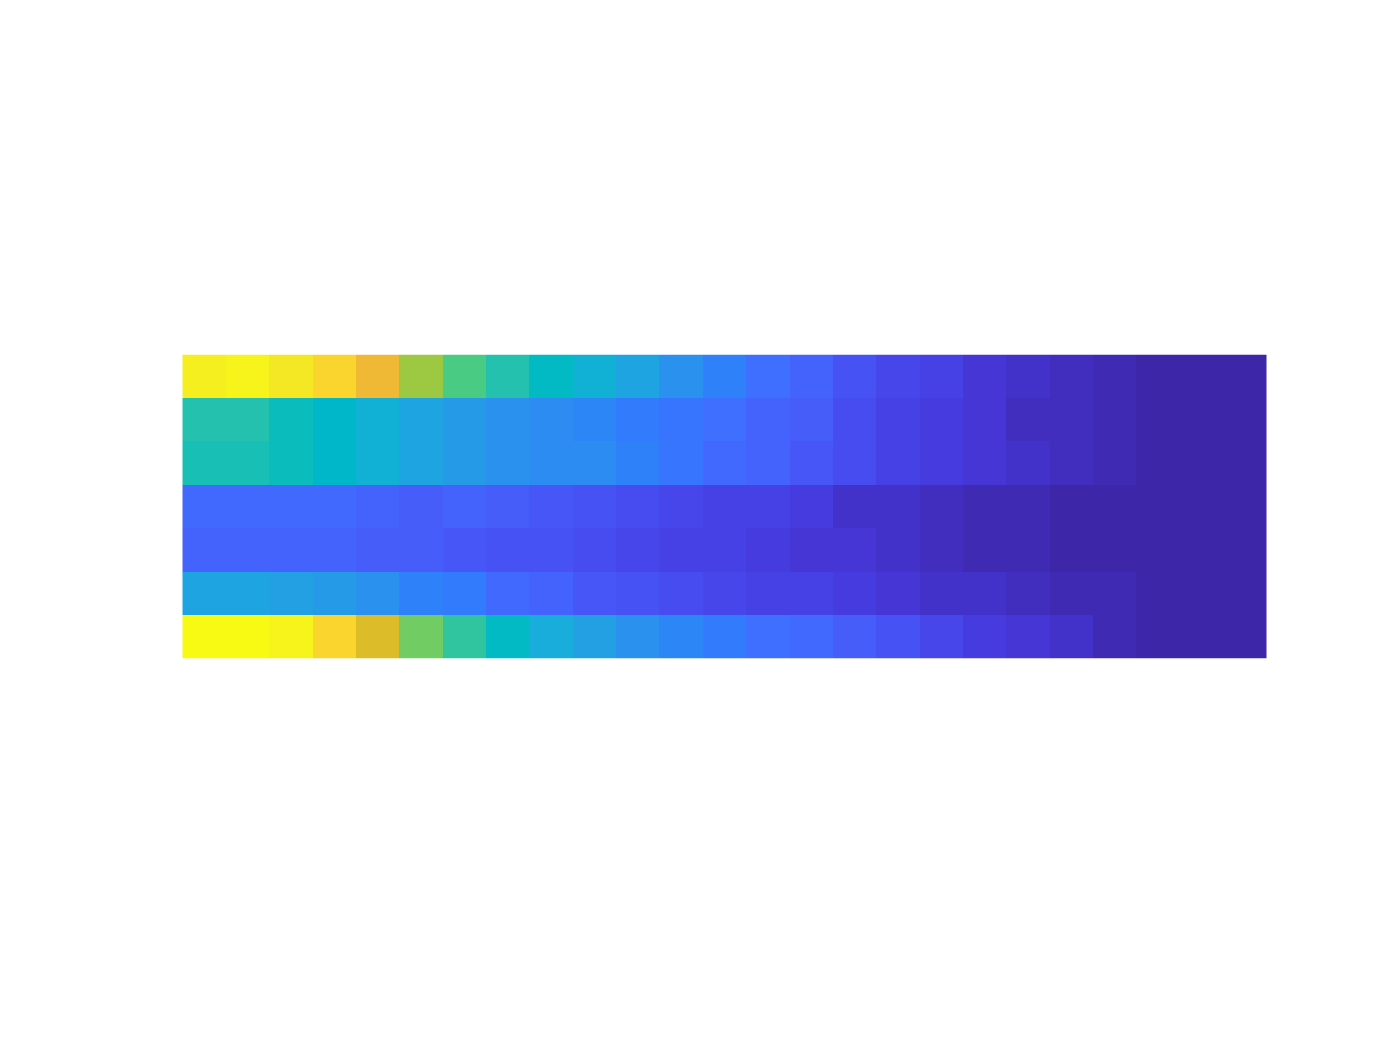

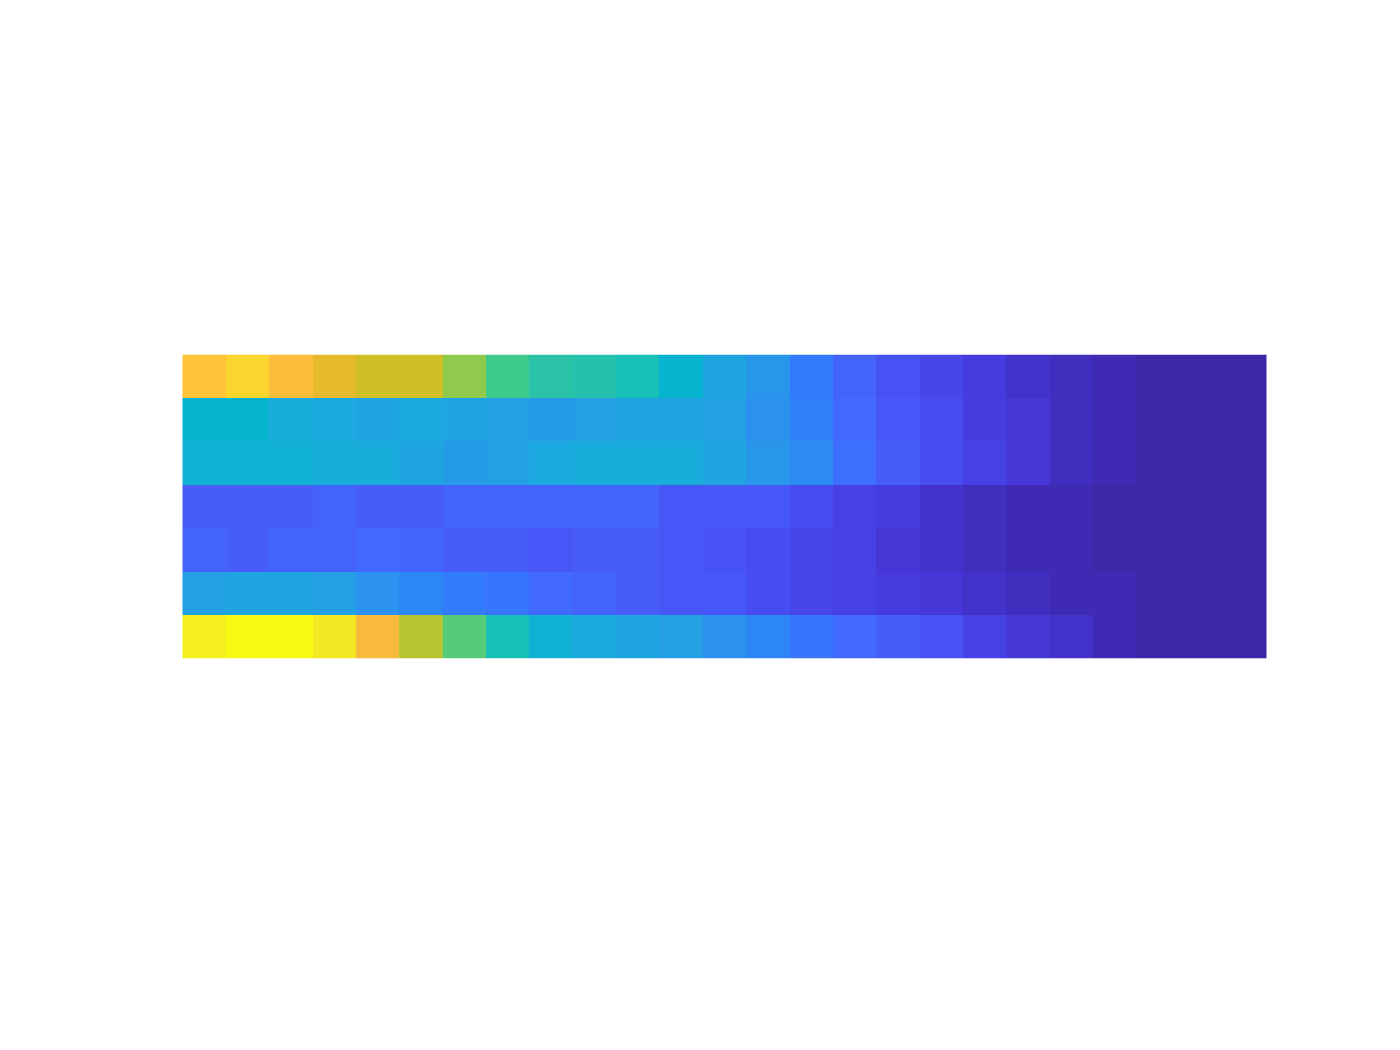

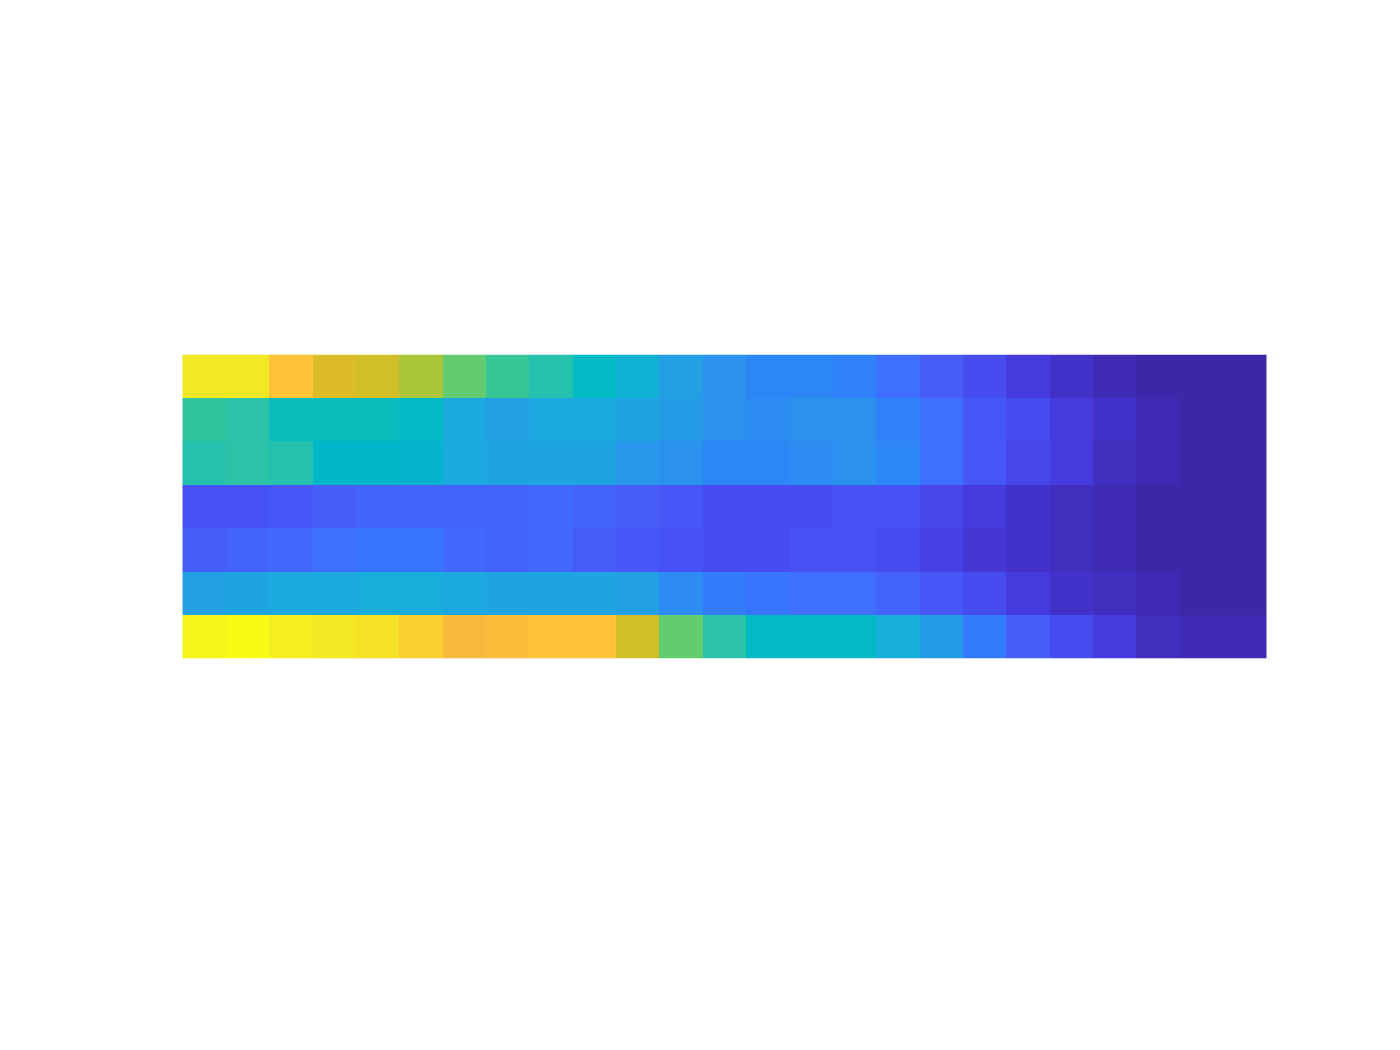

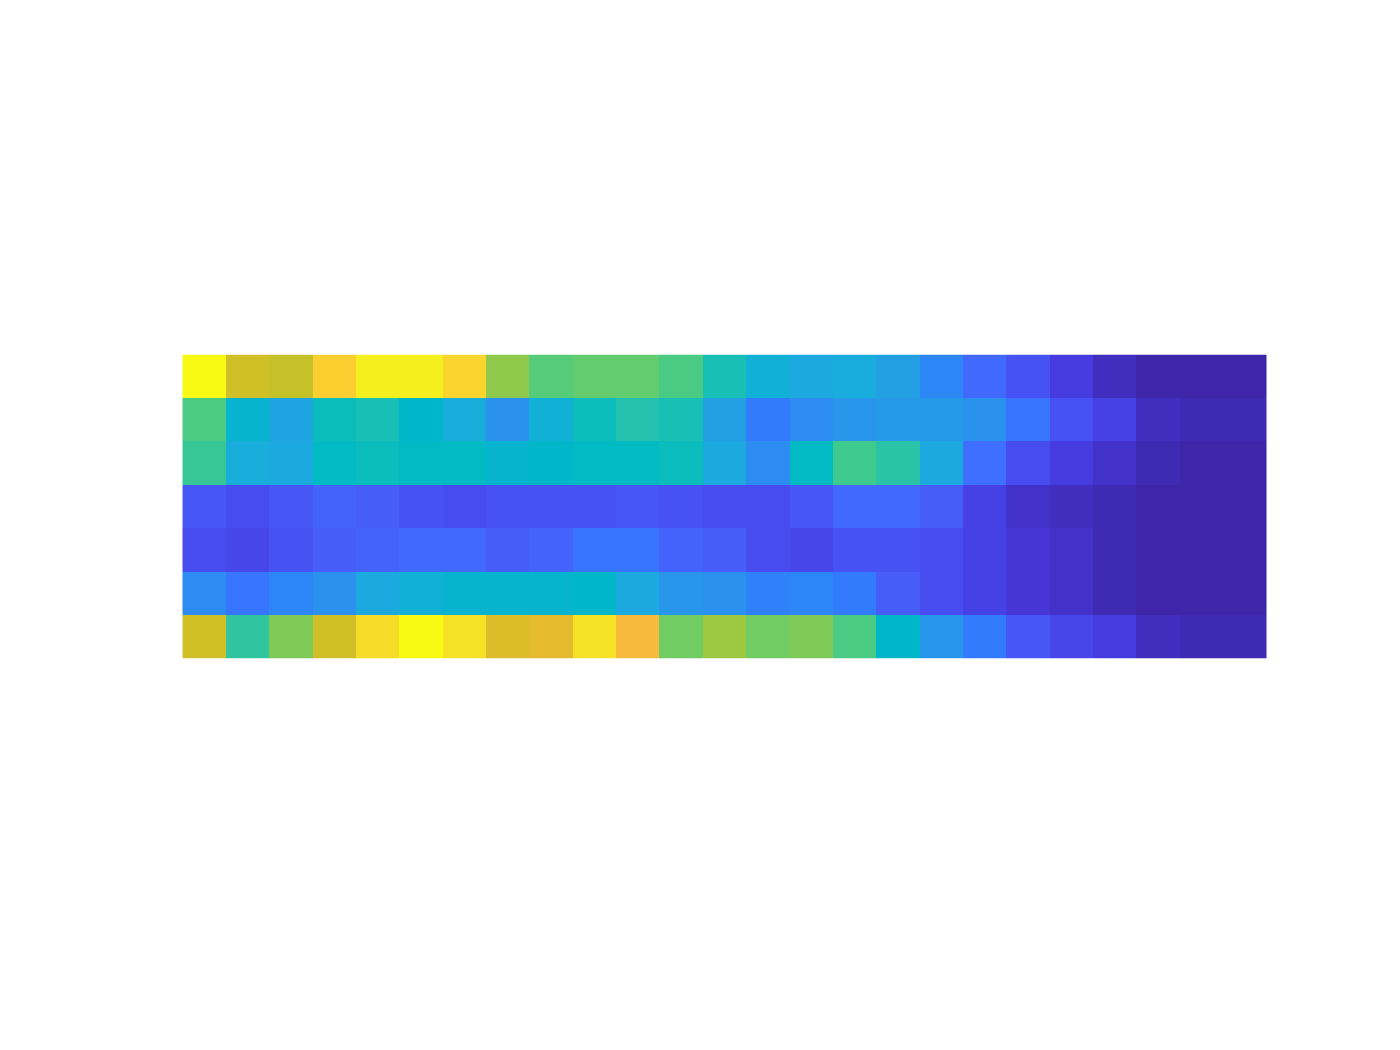

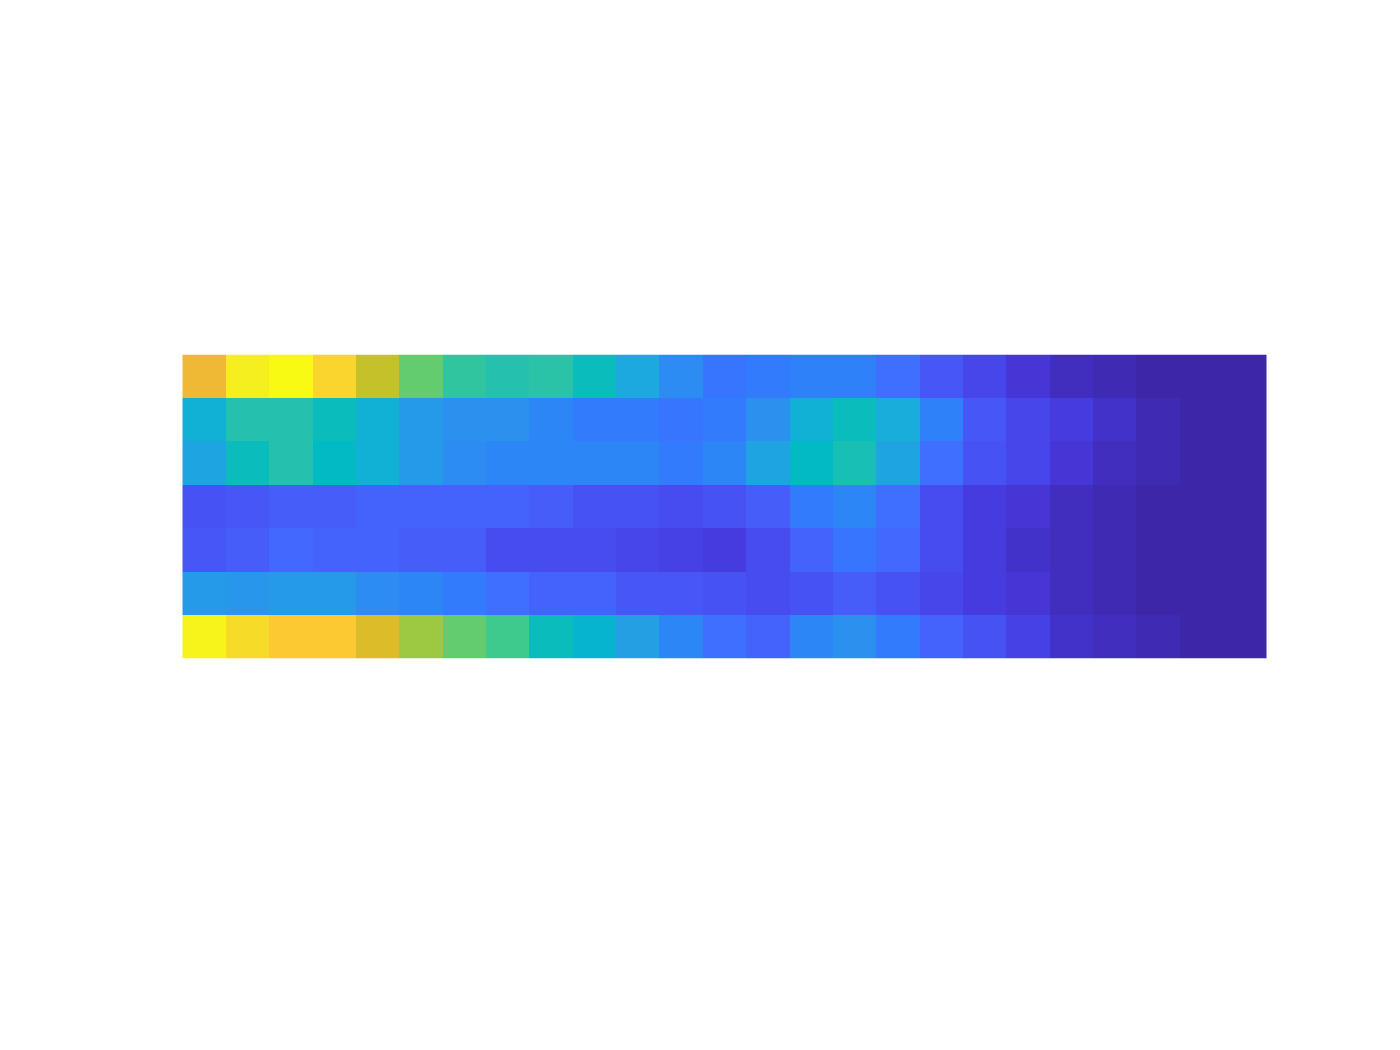

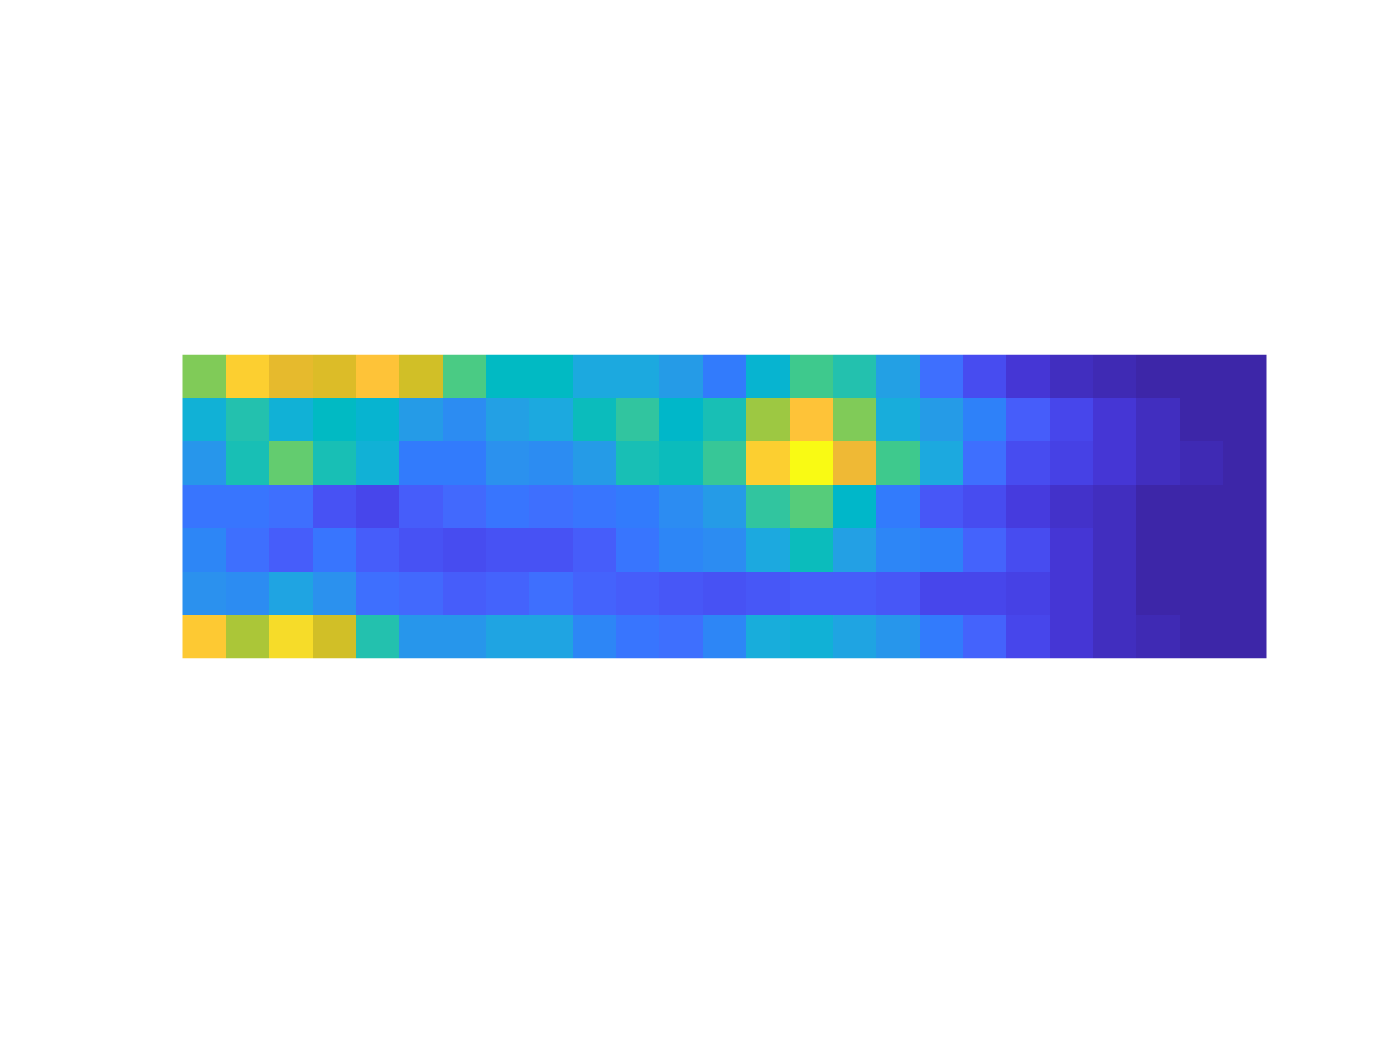

% power spectrum from joints - WT only example
parameters = setRunParameters([]);
parameters.pcaModes = 36;
parameters.samplingFreq = 80;
parameters.minF = .25;
parameters.maxF = 20;
numModes = 36;
numW = 25;
minLength = 20;
maxNum = 100; N = 100;

p1 = jj;
jv = 1:18;
jv2 = [jv jv+18];

p1Center = findP1Center(p1);
p1C = p1Center(jv2,:);
for i = 1:24
    p1C(i,:) = medfilt1(smooth(p1C(i,:),5),5);
end

[W1 a] = findWavelets(p1C',36,parameters);

WR = sC1CON;
G1 = makeGroupsAndSegments({WR},maxNum,1,minLength);

powerW = zeros(numModes,length(W1));
for i = 1:numModes
    idxI = (numW*(i-1)+1):(numW*(i-1)+numW);
    powerW(i,:) = sum(W1(:,idxI),2);
end
BIdx = cell(1,N);
SortedW1 = cell(size(BIdx));

for i = 1:N
    gtemp = G1{i};
    btemp = [];
    SW1t = cell(size(gtemp,1),1);
    for j = 1:size(gtemp,1)
        btemp = [btemp gtemp(j,2):gtemp(j,3)];
        SW1t{j} = W1(gtemp(j,2):gtemp(j,3),:);
    end
    BIdx{i} = btemp;
    SortedW1{i} = SW1t;
end

allW = cell(size(BIdx));
allP = cell(size(BIdx));
for i = 1:N
    allW{i} = W1(BIdx{i},:);
    allP{i} = p1C(:,BIdx{i});
end

allWM = zeros(36,25,N);
l_w = zeros(1,N);
for i = 1:N
    tempwm = mean(allW{i},1);
    l_w(i) = size(allW{i},1);
    allWM(:,:,i) = reshape(tempwm,[25 36])';
end

L_W = l_w;
BIG_W = allWM;

W_all = zeros(36,25,N);
L_all = zeros(1,N);
for i = 1:N
    TW = zeros(36,25);
    TL = 0;
    
    tw = BIG_W(:,:,i);
    tl = L_W(i);
    if sum(sum(isnan(tw)))==0
        TW = TW+tw;
        TL = TL+tl;
    end
    
    W_all(:,:,i) = TW./TL;
    L_all(i) = TL;
end

wxall = W_all(1:18,:,:);
wyall = W_all(19:end,:,:);

Wxy = sqrt(wxall.^2+wyall.^2);

juse1 = [1 8 7 12 13 17 18]; % snout, linbs, tail
for b = 1:8
    figure;
    imagesc(Wxy(juse1,:,b)./sum(sum(Wxy(juse1,:,b)))); axis off equal
end